# Opgave 3

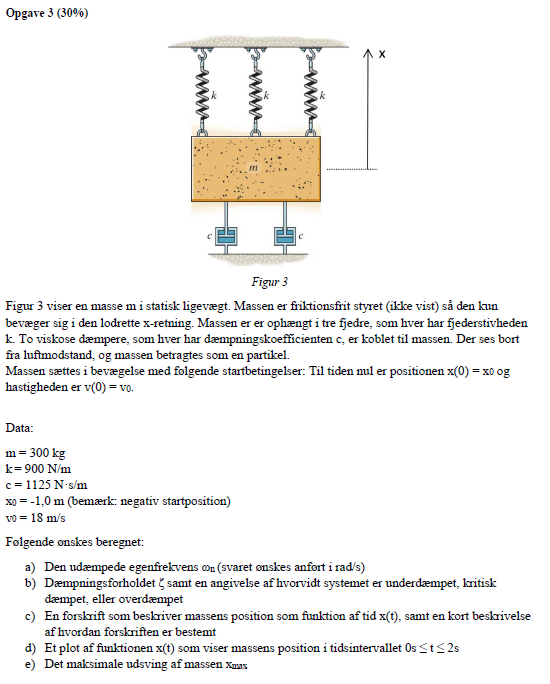

## Opgave a)

Eftersom der er 3 fjedre i en parallelkobling, ganges fjederkonstanten k med 3

clear
% Data til opgaven
m = 300;    % kg
k = 900 * 3;    % N/m % paralel koblede
c = 1125;   % Ns/m
x0 = -1;    % m
v0 = 18;    % m/s

wn = sqrt(k/m)

wn = 3

Svar til opgave a

Egenfrekvensen bliver


$$\omega_n = \sqrt{\frac{k}{m}} = 3 \frac{rad}{s}$$


## Opgave b)

Igen, her er der 2 dæmpere, så dæmpningskoefficienten ganges med 2

c = 2*c; % Frem herefter er den brugte c i formler = 2*c
zeta = c/(2*m*wn)

zeta = 1.2500

Svar til opgave b

Udregning af dæmpningsforhold giver


$$\zeta = \frac{c}{2m\omega_n} = 1.25$$


Hvilken betyder der er med en overdæmpet svingning at gøre

## Opgave c)

Forklaring under

t0 = 0;
t1 = 2;


syms A1 A2 t x1

% Ligning 8/10 fra bogen benyttes og sættes lig startpositionen
x_plac_t0 = A1*exp((-zeta + sqrt(zeta^2 - 1))*wn*t) + A2*exp((-zeta-sqrt(zeta^2-1))*wn*t) == x0

$$x\_plac\_t0 = A_{1}\,{\mathrm{e}}^{-\frac{3\,t}{2}}+A_{2}\,{\mathrm{e}}^{-6\,t}=-1$$

x_plac_t1 = A1*exp((-zeta + sqrt(zeta^2 - 1))*wn*t) + A2*exp((-zeta-sqrt(zeta^2-1))*wn*t) == x1;

% Hastigheden kommer fra at differentiere placeringsfunktionen, og sætte
% den lig starthastigheden
x_vel = diff(lhs(x_plac_t0), t) == v0

$$x\_vel = -\frac{3\,A_{1}\,{\mathrm{e}}^{-\frac{3\,t}{2}}}{2}-6\,A_{2}\,{\mathrm{e}}^{-6\,t}=18$$


% Ligningerne og de ukendte løses
eqs = [x_plac_t0, x_vel];
vars = [A1, A2];

sols = solve(eqs, vars)

sols = struct with fields:
    A1: (8*exp((3*t)/2))/3
    A2: -(11*exp(6*t))/3



% Konstanterne A1 og A2 udregnes, og sættes ind i diff ligningerne til
% tiden t0

A1_ny = vpa(subs(sols.A1, t, t0),4)

$$A1\_ny = 2.667$$

A2_ny = vpa(subs(sols.A2, t, t0),4)

$$A2\_ny = -3.667$$


% Funktionen præsenteres
funktion = vpa(subs(lhs(x_plac_t1), [A1, A2], [A1_ny, A2_ny]),4)

$$funktion = 2.667\,{\mathrm{e}}^{-1.5\,t}-3.667\,{\mathrm{e}}^{-6.0\,t}$$

Svar til opgave c)

Da det er fundet at der er med en overdæmpet funktion at gøre, bruges formel 8/10 i bogen (her er den kaldt $x_{plac, t_0}$), og der løses for konstanterne A1 og A2.

De tidligere udregnede værdier for 


$$\zeta = 1.25$$



$$\omega_n = 3$$


Er brugt i formlen.

Når der er løst for A1 og A2, som hhv er


$$A_1 = 2,667$$



$$A_2 = -3,667$$


Indsættes de i startformlen 8/10, og følgende funktion fås


$$x(t) = 2,667e^{1,5\cdot t} - 3,667e^{-6\cdot t}$$


## Opgave d)

Funktionen plottes i det givne interval for tiden 0 til 2 sekunder

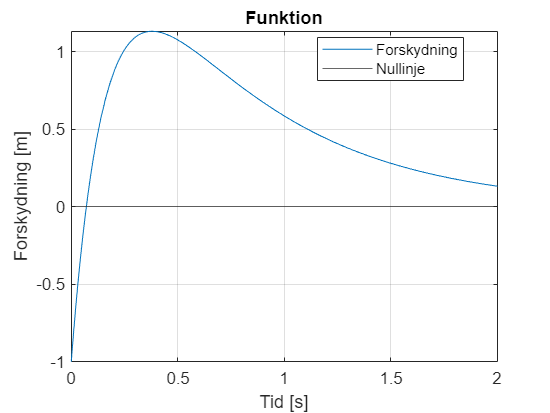

syms func(t)
xp = x0;

func(t) = A1_ny*exp((-zeta + sqrt(zeta^2 - 1))*wn*t) + A2_ny*exp((-zeta-sqrt(zeta^2-1))*wn*t);

fplot(func(t), [t0,t1], "DisplayName", "Forskydning"), xlabel("Tid [s]"), ylabel("Forskydning [m]"), grid()
yline(t0, "DisplayName", "Nullinje")

title("Funktion");

legend("Location","best")

Hvor det ses at til t = 0 er forskydningen x(0) = -1, som det også var opgivet i opgaven

## Opgave e)

Det maksimale udsving af massen findes

tlin = linspace(0, 2, 1000);

xmax = A1_ny*exp((-zeta + sqrt(zeta^2 - 1))*wn*tlin) + A2_ny*exp((-zeta-sqrt(zeta^2-1))*wn*tlin);

[xmax, I] = max(xmax);

maks = vpa(xmax,5)

$$maks = 1.133$$

tid = vpa(tlin(I),4)

$$tid = 0.3784$$

I funktionen fundet i opgaven c) er der søgt efter en maksimalværdi, som er fundet til 


$$x_{max} = 1.133m$$


til tiden


$$t = 0.3784s$$


Det er det maksimale udsving fra startpositionen

mere præcist

syms t
xmax = A1_ny*exp((-zeta + sqrt(zeta^2 - 1))*wn*t) + A2_ny*exp((-zeta-sqrt(zeta^2-1))*wn*t);

xmax_diff = diff(xmax, t)
tmax_sol = solve(xmax_diff == 0, t)

t_max = subs(xmax, t, tmax_sol)